## Drift

mat = [10 0.300 0.050 10 0.540 0.050 10 0.920 0.030
20 0.32 0.11 20 0.610 0.050 20 1.100 0.050
30 0.25 0.15 30 0.430 0.080 30 0.97 0.11
40 0.23 0.21 40 0.30 0.11 40 0.80 0.15
50 0.15 0.31 50 0.40 0.14 50 0.75 0.21];

DUT = string(mat(:,1))

DUT = 5×1 string array
    "10"
    "20"
    "30"
    "40"
    "50"


e_kal_2018 = mat(:,2);
u_e_kal_2018 = mat(:,3);
e_kal_2019 = mat(:,5);
u_e_kal_2019 = mat(:,6);
e_kal_2020 = mat(:,8);
u_e_kal_2020 = mat(:,9);


drift_18_19 = e_kal_2019 - e_kal_2018

drift_18_19 =     0.2400
    0.2900
    0.1800
    0.0700
    0.2500


drift_19_20 = e_kal_2020 - e_kal_2019

drift_19_20 =     0.3800
    0.4900
    0.5400
    0.5000
    0.3500


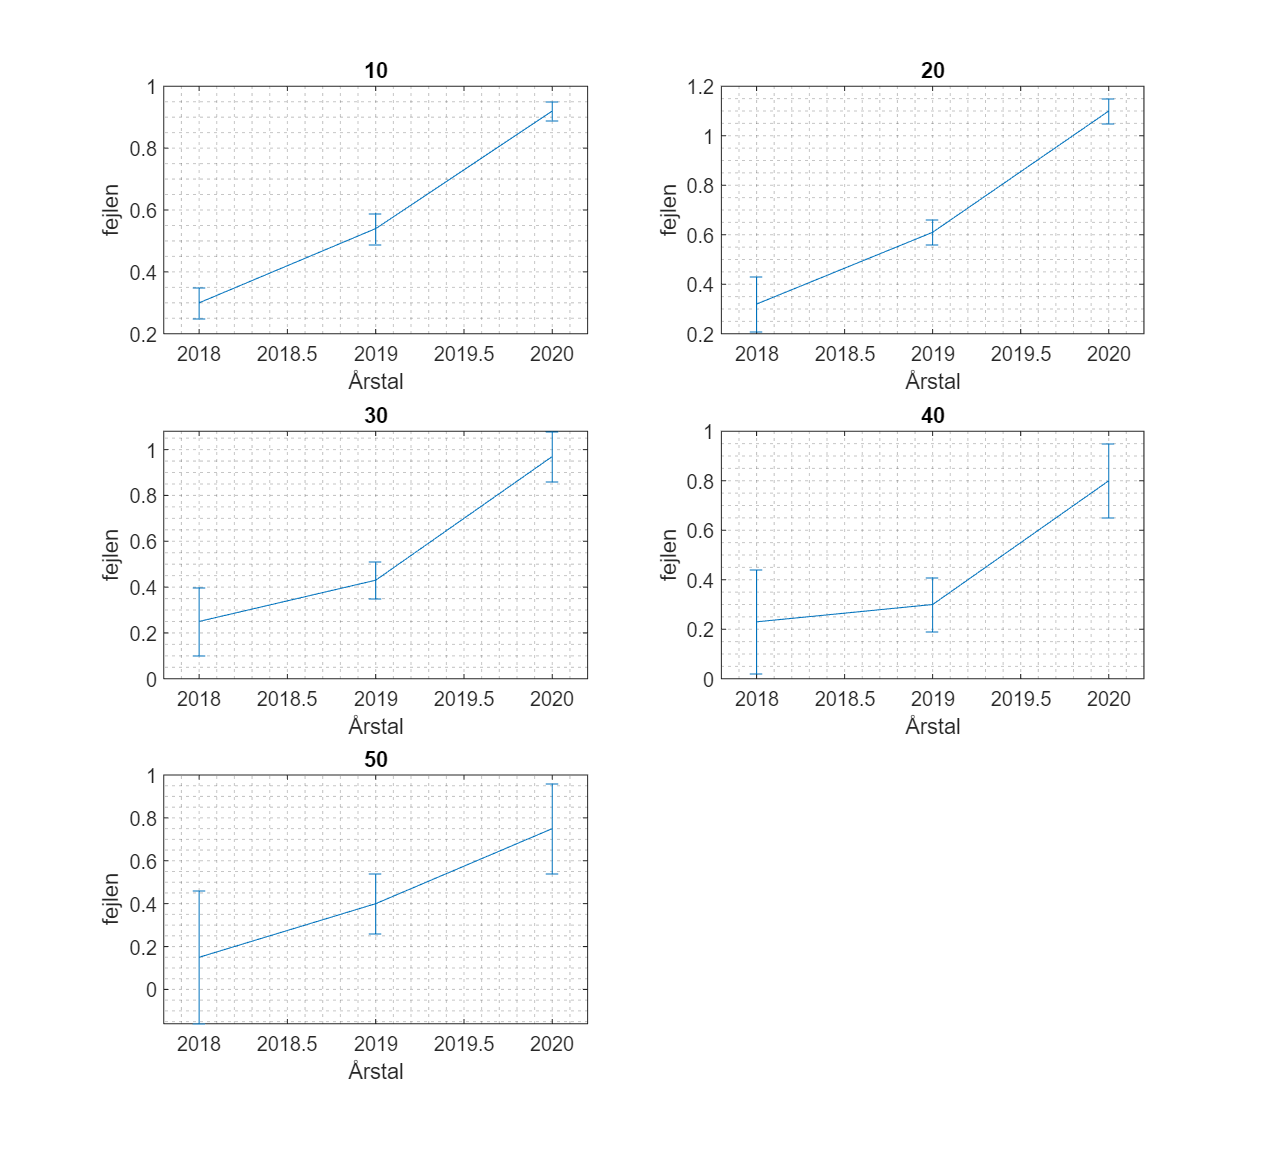

clf
% hold on


figure
pos = get(gcf, 'Position');
set(gcf, 'Position',pos+[0 -500 1000 1000])

for i = 1:size(mat,1)
    subplot(3,2,i);
    errorbar([2018, 2019, 2020], [e_kal_2018(i), e_kal_2019(i), e_kal_2020(i)], [u_e_kal_2018(i), u_e_kal_2019(i), u_e_kal_2020(i)]);
    grid('minor')
    title(DUT(i))
%     legend(DUT(i), Location="best")
    xlabel('Årstal')
    ylabel('fejlen')
    xlim([2017.8, 2020.2])
end


% hold off
table(mat)

ans = 5×1 table
       mat    
    __________

    1×9 double
    1×9 double
    1×9 double
    1×9 double
    1×9 double


1.83 - 1.32

ans = 0.5100

0.12 + 0.35

ans = 0.4700


a = [12.02
11.96
11.90
12.00
12.02];
std(a)

ans = 0.0510


tinv(0.95, 5)

ans = 2.0150

tpdf()